# 信号与系统大作业报告

冯绍庭 520021911362

## Project 1

1) I selected a clip of audio and denote it as x_n. I used zero-order hold to construct the continuous time counterpart x(t), and showed its signal waveform.  

The **zero-order hold** is a method which is widely used to reconstruct the signals in real time. In the zero-order hold reconstruction method, the continuous signal is reconstructed from its samples by holding the given sample for an interval until the next sample is received. Therefore, the zero-order hold generates the step approximations.

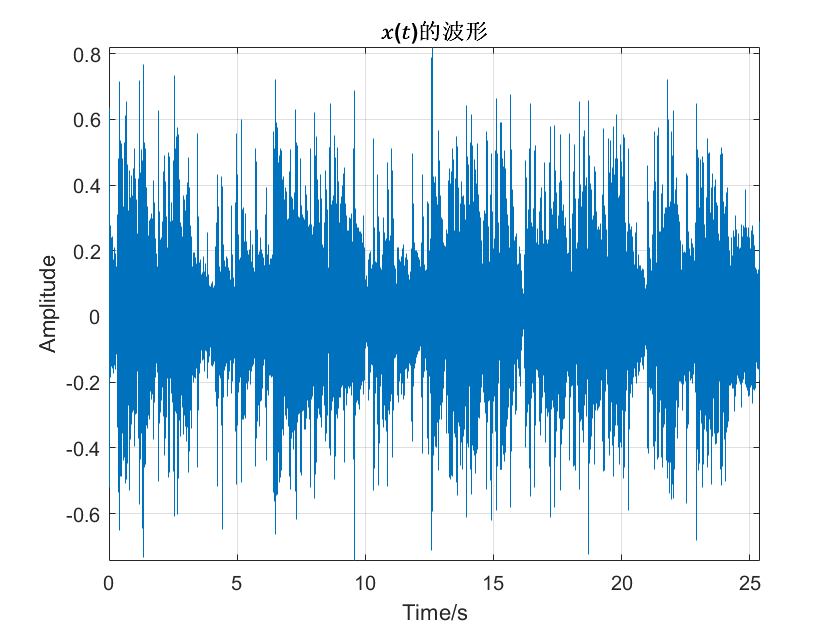

[X,Fs] = audioread('17岁女生的温柔-李宗盛.mp3');
x_n = X(1120000:2239999,1); % 截短+双声道歌曲提取第一个声道
x_n = x_n';
N = length(x_n); % 求取抽样点数
t = (0:N-1) / Fs; % 显示实际时间
sound(x_n,Fs) % 播放检验效果

stairs(t,x_n); % zero-order hold
xlabel('Time/s');
ylabel('Amplitude');
title('𝑥(𝑡)的波形');
axis tight 
grid;

2) The waveforms of x(-t), x(2t), and x(t/2) are as follows.  

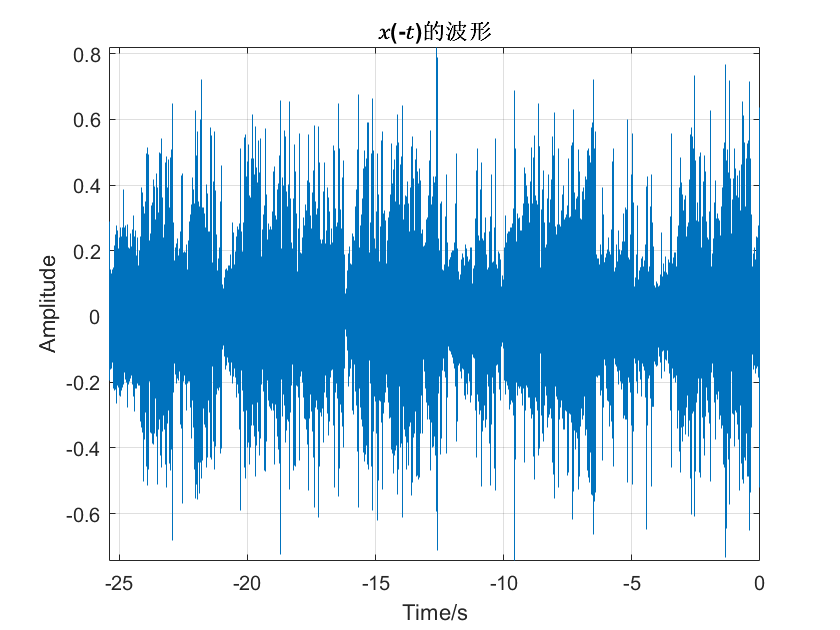

x_minus = fliplr(x_n);
t_minus = t - (N-1)/Fs;
stairs(t_minus,x_minus); 
xlabel('Time/s');
ylabel('Amplitude');
title('𝑥(-𝑡)的波形');
axis tight 
grid;

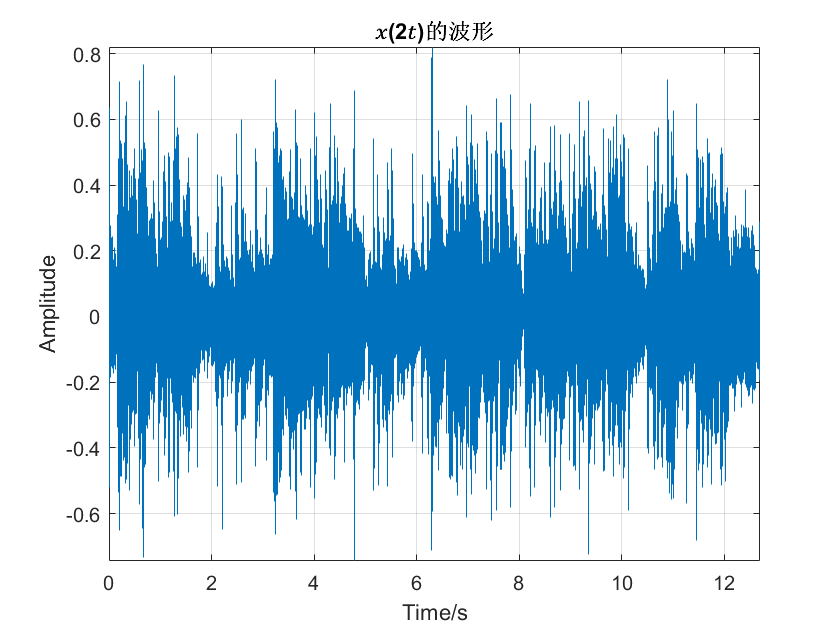

t2 = t/2;
stairs(t2,x_n); 
xlabel('Time/s');
ylabel('Amplitude');
title('𝑥(2𝑡)的波形');
axis tight 
grid;

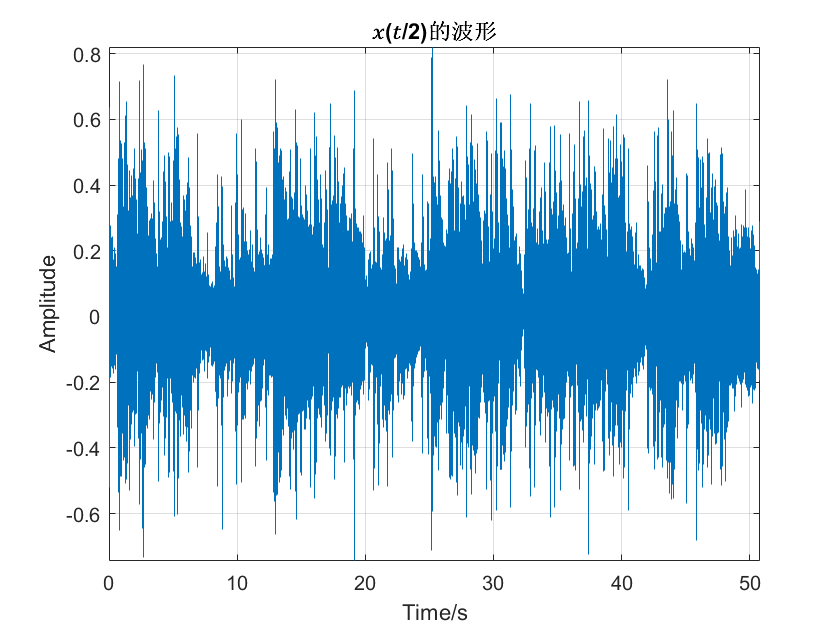

t3 = 2 * t;
stairs(t3,x_n); 
xlabel('Time/s');
ylabel('Amplitude');
title('𝑥(𝑡/2)的波形');
axis tight 
grid;

3) For the Fourier transform of x(-t), x(2t), and x(t/2), I first calculated the Fourier transform of x(t). Then I used the following property of the Fourier Transform to draw the spectra:


$$x\left(t\right)\leftrightarrow X\left(j\omega \right)\Rightarrow x\left(at\right)\leftrightarrow \frac{1}{{\left|a\right|}}X\left(j\frac{\omega }{a}\right)$$


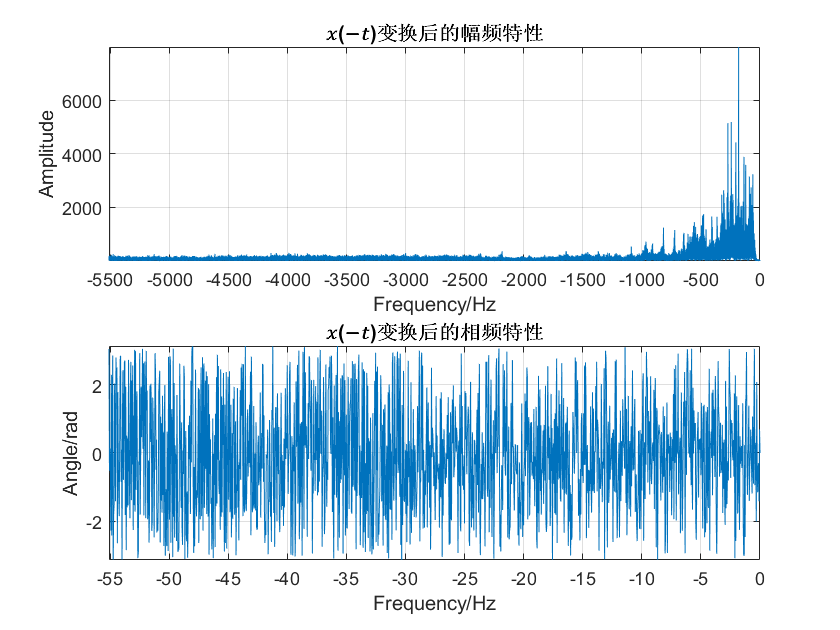

y = fft(x_n); % 对信号进行傅里叶变换
f = Fs / N * (0:N-1); % 频率
f_A = f(1:round(N/8)); % 显示实际频点的八分之一，频域映射，转化为HZ
f_theta = f(1:round(N/800)); % 对于相频特性，显示实际频点的八百分之一

f_A1 = -f_A; % 显示实际频点的八分之一，频域映射，转化为HZ
f_theta1 = -f_theta; % 对于相频特性，显示实际频点的八百分之一

subplot(211);
plot(f_A1,abs(y(1:round(N/8))));
xlabel('Frequency/Hz');
ylabel('Amplitude');
title('𝑥(−𝑡)变换后的幅频特性');
axis tight;
grid;

subplot(212);
plot(f_theta1,angle(y(1:round(N/800))));
xlabel('Frequency/Hz');
ylabel('Angle/rad');
title('𝑥(−𝑡)变换后的相频特性');
axis tight;
grid;

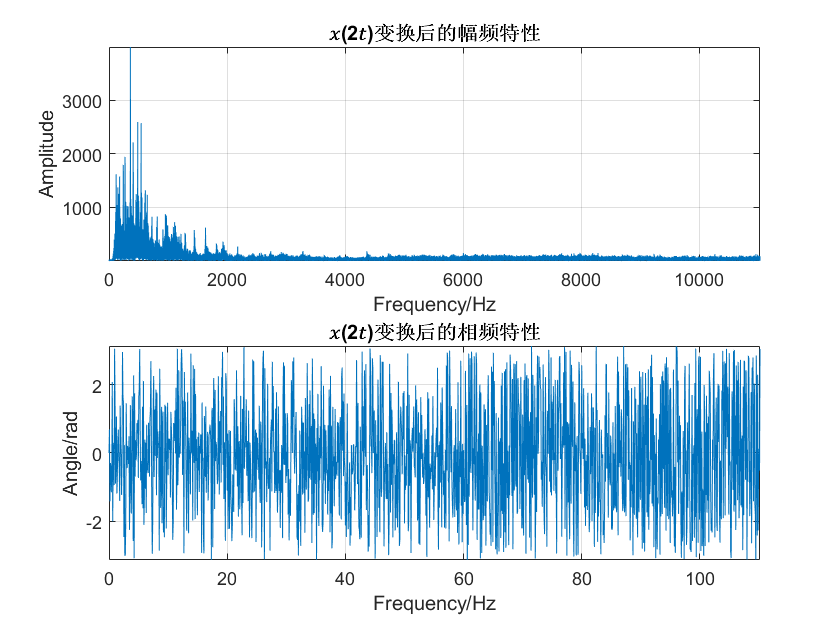

y2 = y / 2;
f_A2 = 2 * f_A;
f_theta2 = 2 * f_theta;
subplot(211);
plot(f_A2,abs(y2(1:round(N/8))));
xlabel('Frequency/Hz');
ylabel('Amplitude');
title('𝑥(2𝑡)变换后的幅频特性');
axis tight;
grid;

subplot(212);
plot(f_theta2,angle(y2(1:round(N/800))));
xlabel('Frequency/Hz');
ylabel('Angle/rad');
title('𝑥(2𝑡)变换后的相频特性');
axis tight;
grid;

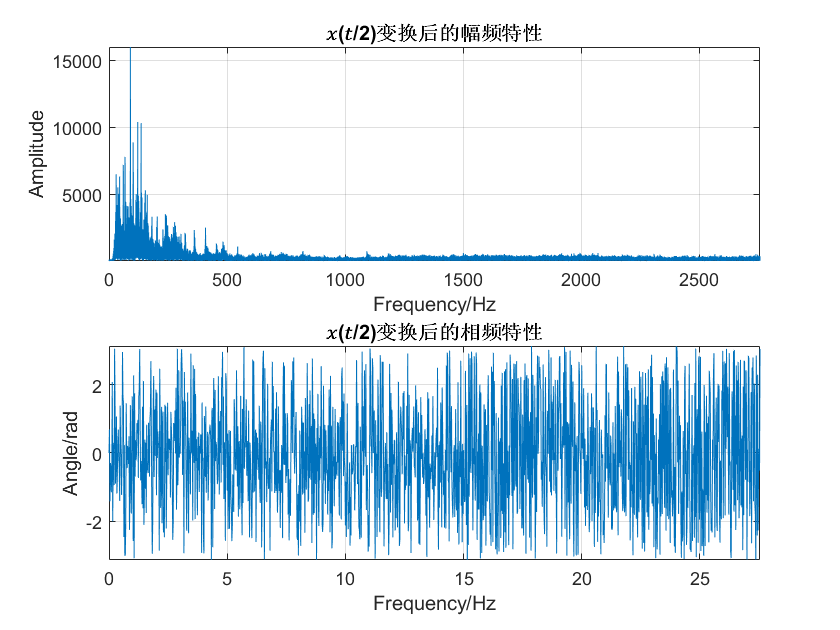

y3 = 2 * y;
f_A3 = f_A / 2;
f_theta3 = f_theta / 2;
subplot(211);
plot(f_A3,abs(y3(1:round(N/8))));
xlabel('Frequency/Hz');
ylabel('Amplitude');
title('𝑥(𝑡/2)变换后的幅频特性');
axis tight;
grid;

subplot(212);
plot(f_theta3,angle(y3(1:round(N/800))));
xlabel('Frequency/Hz');
ylabel('Angle/rad');
title('𝑥(𝑡/2)变换后的相频特性');
axis tight;
grid;

Both the amplitude-frequency characteristic and the magnitude-frequency characteristic can be generated from the Fourier transform of the original signal with reflection, streches and compression.

4) Denote X(j$\omega$) as the Fourier transform of x(t). The waveform of the inverse Fourier transform of the magnitude spectrum ${\mathcal{F}}^{-1}${|X(j$\omega$)|} is as followed.

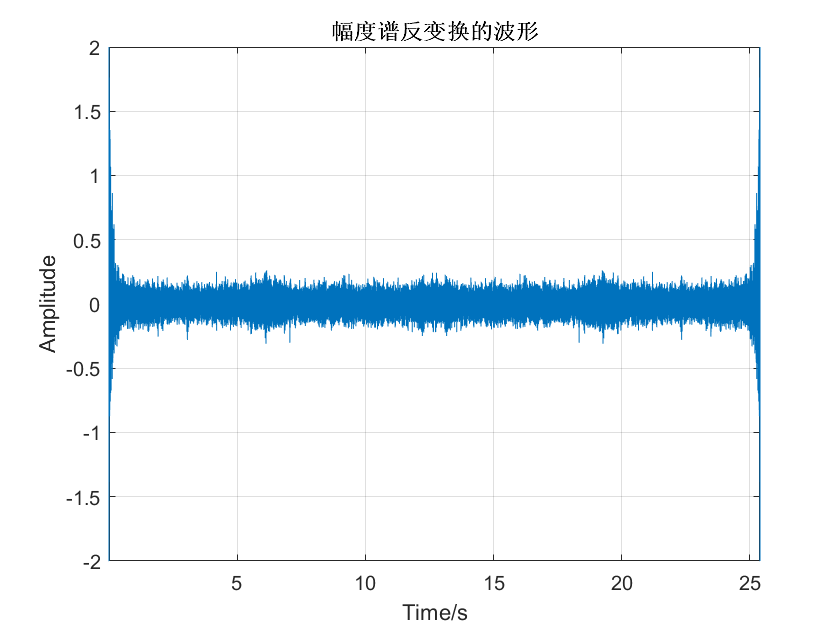

amp = abs(y);
yi = ifft(amp);
figure;
plot(t,yi); % 绘制时域波形
xlabel('Time/s');
ylabel('Amplitude');
title('幅度谱反变换的波形');
axis tight;
ylim([-2 2])
grid;

The waveform of the inverse Fourier transform of the phase spectrum ${\mathcal{F}}^{-1}${${\textrm{𝑒}}^{\textrm{j∡𝑋}\left(\textrm{𝑗𝜔}\right)}$} is as followed. 

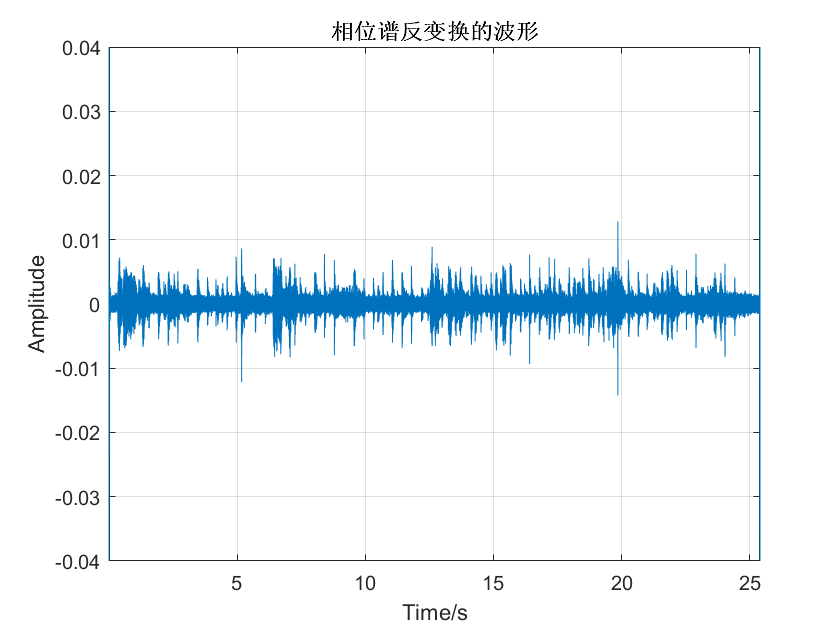

ang = angle(y);
testang = exp(1i * ang);
yii = ifft(testang);
plot(t,real(yii)); % 绘制时域波形
xlabel('Time/s');
ylabel('Amplitude');
title('相位谱反变换的波形');
axis tight;
ylim([-0.04 0.04])
grid;

Neither of them is similar to the original signal. So I tried to reconfigure the original signal using inverse Fourier transform.

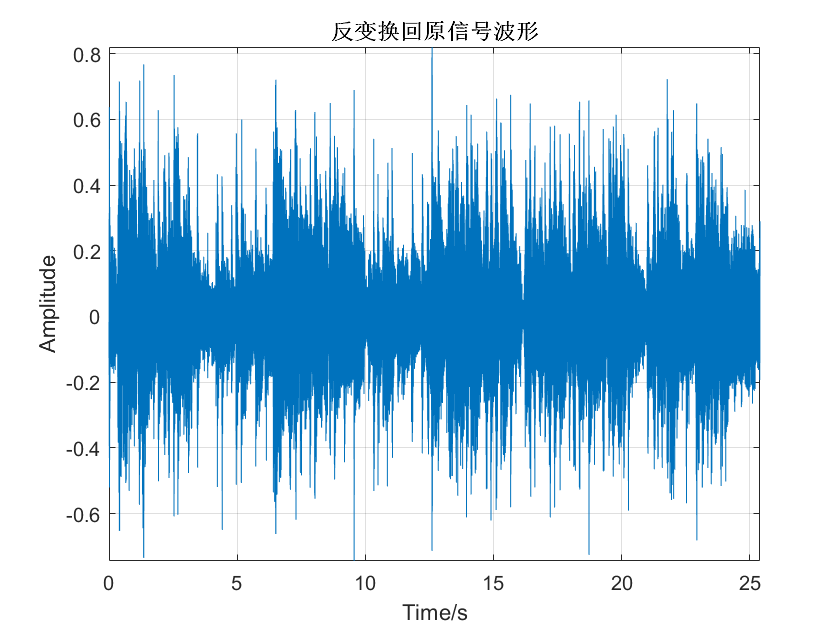

test = amp .* testang;
yiii = ifft(test);
plot(t,real(yiii)); % 绘制时域波形
xlabel('Time/s');
ylabel('Amplitude');
title('反变换回原信号波形');
axis tight;
grid;

It turned out that the waveform of ${\mathcal{F}}^{-1}${|X(j$\omega$)|$\cdot$${\textrm{𝑒}}^{\textrm{j∡𝑋}\left(\textrm{𝑗𝜔}\right)}$} looks exactly the same as that of 𝑥(𝑡).

5) I implemented a low-pass filtering to x(t) in the frequency domain and set the band to 700Hz. The spectrum is as followed. 

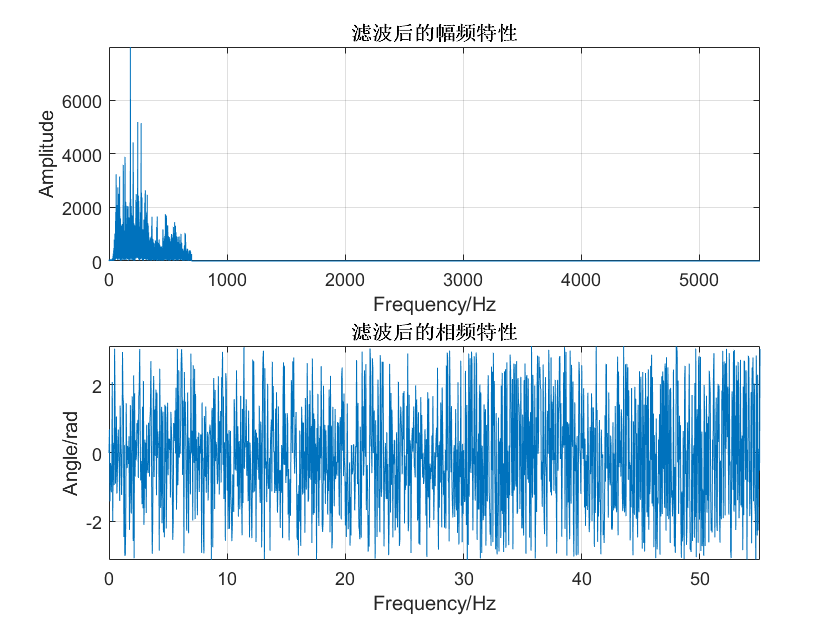

f_end = 700; % 自定义截止频率
y_end = y;
y_end(f>f_end) = 0;

subplot(211);
plot(f_A,abs(y_end(1:round(N/8))));
xlabel('Frequency/Hz');
ylabel('Amplitude');
title('滤波后的幅频特性');
axis tight;
grid;

subplot(212);
plot(f_theta,angle(y_end(1:round(N/800))));
xlabel('Frequency/Hz');
ylabel('Angle/rad');
title('滤波后的相频特性');
axis tight;
grid;

Since the phase-frequency characteristic is so dense that if I select many frequency, it will look like a blue rectangle. I only chose very low frequency and the diagram has no difference,

The waveform of the resulting signal is as followed. I compared it with the original signal.

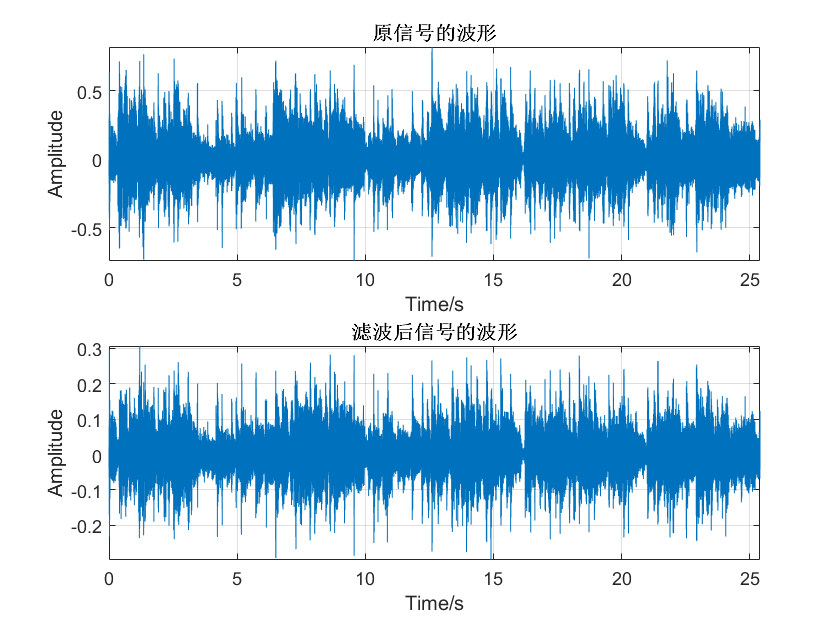

subplot(211);
plot(t,x_n); % 绘制时域波形
xlabel('Time/s');
ylabel('Amplitude');
title('原信号的波形');
axis tight;
grid;

x_end = ifft(y_end);
subplot(212);
plot(t,real(x_end)); % 绘制时域波形
xlabel('Time/s');
ylabel('Amplitude');
title('滤波后信号的波形');
axis tight;
grid;

sound(real(x_end),Fs);  

The music sounds really fuzzy.

## Project 2 Voice Eliminator

In the following section, I will introduce how I created the  'Voice_Eliminator.m' which can eliminate the voice of the singer in the song. The principles behind the steps will be discussed along.

### Step 1  Extract Left and Right Channel

For ordinary **stereo** songs, the reason why people can feel the stereo is that the **accompaniment** of the left and right channels is **different** in frequency, amplitude and phase, while the **human voice** is basically the **same** in the left and right channels.

We denote the original signal as Track 1, the left channel as Track 2, and the right channel as Track 3.

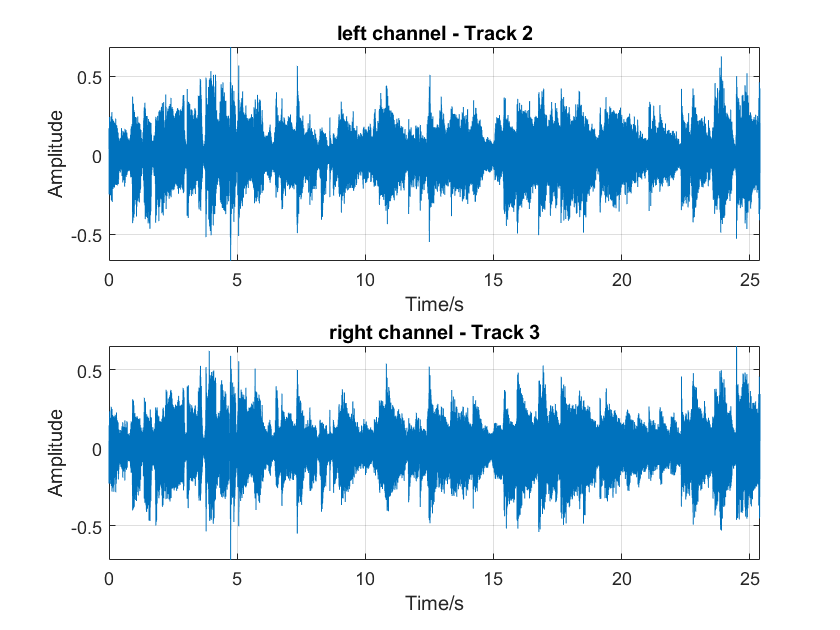

[X,Fs] = audioread('五月天-突然好想你 (电视剧《姊妹》插曲).mp3');
x_n1 = X(1120000:2239999,:); % x_n1 - Track 1
audiowrite('原曲.mp4',x_n1,Fs);
sound(x_n1,Fs);

x_n2 = x_n1(:,1); % x_n2 - Track 2
x_n3 = x_n1(:,2); % x_n3 - Track 3

N = length(x_n2); % 求取抽样点数
t = (0:N-1) / Fs; % 显示实际时间

subplot(211);
plot(t,x_n2); 
xlabel('Time/s');
ylabel('Amplitude');
title('left channel - Track 2');
axis tight;
grid;
subplot(212);
plot(t,real(x_n3)); % 绘制时域波形
xlabel('Time/s');
ylabel('Amplitude');
title('right channel - Track 3');
axis tight;
grid;

### Step 2 Phase Reverse

We apply **phase reverse** to track 3, using fft and inverse fft.

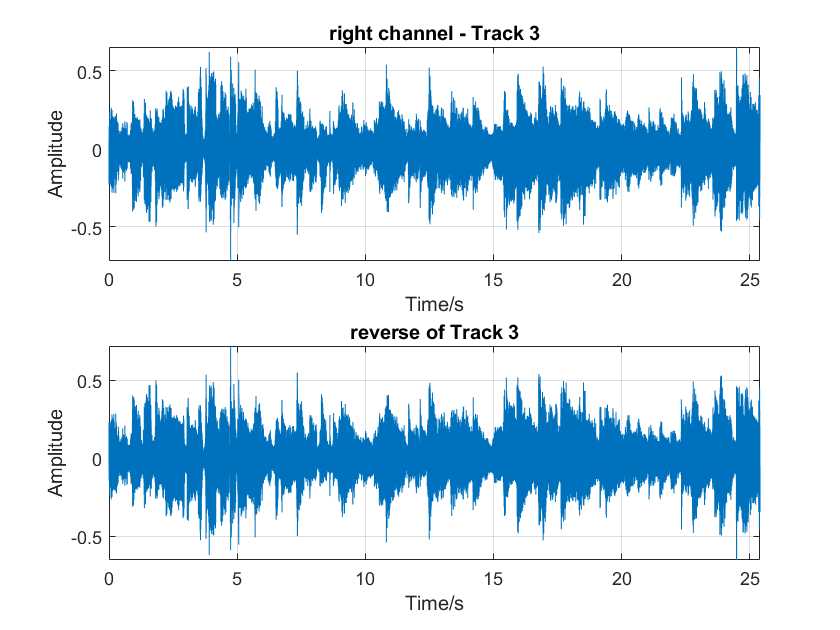

y_n3 = fft(x_n3);
amp = abs(y_n3);
ang = angle(y_n3) + pi;
exp_ang = exp(1i * ang);
y_n3_reverse = amp .* exp_ang;
x_n3_reverse = ifft(y_n3_reverse);

subplot(211);
plot(t,x_n3); 
xlabel('Time/s');
ylabel('Amplitude');
title('right channel - Track 3');
axis tight;
grid;
subplot(212);
plot(t,real(x_n3_reverse)); 
xlabel('Time/s');
ylabel('Amplitude');
title('reverse of Track 3');
axis tight;
grid;

### Step 3 Mixing

We mix the Track 2 and the reverse of Track 3 and denote it as Track 4.

When two audio signals with the same amplitude and frequency are out of phase, there is no difference between the two sounds heard by the human ear, and **after adding the two audio signals with the same amplitude, frequency and phase difference **$\pi$**, the sound is eliminated**. 

x_n4 = (x_n2 + x_n3_reverse) / 2;
sound(real(x_n4),Fs);  

Now there still exist several weak clips of vocal and the sound of "ShaShaWuWu...". The result is acceptable, but still needs improvement.

### Step 4 Filtering

Duplicate Track 4 to two new tracks for later compensation, Track5 and Track6. Apply a **high-pass filter** to Track 5, and a **low-pass filter to Track 6**. These frequencies are not fixed, but need to be carefully adjusted according to different songs.

Hh = highpass;
x_n5 = filter(Hh,x_n4); % x_n5 - Track 5
Hl = lowpass;
x_n6 = filter(Hl,x_n4); % x_n6 - Track 6

### Step 5 Compensation

When extracting the accompaniment, we will perform some corresponding processing on certain instruments and sounds. Therefore, when we use the above method to make the accompaniment: "the chorus is reversed and distributed to the left and right channels", the chorus part of the monophonic accompaniment signal we get is often strengthened; the bass and the kick drum are attenuated accordingly; at the same time, the high frequencies of some instruments are canceled out or noisy. In addition, the accompaniment obtained by subtracting the left and right is a mono signal, and the sound field is too narrow, so we need to add some original signals to widen the sound field to a certain extent. While using the original signal, we do not want the original singing part in the original signal. The frequency signal is added to our accompaniment. For these reasons, we use some low and high frequency compensation.

x_n7 = (x_n4 + x_n5 + x_n6) / 2;
sound(real(x_n7),Fs);  
audiowrite('v7.mp4',real(x_n7),Fs);